# **第8讲 符号运算**

**8.1  **`符号对象: sym, syms`

**8.2**  `数值与符号变量的相互转换: digits, vpa, double, poly2sym`

**8.3**  `符号矩阵与运算：+、-、*、/`

**8.4**  `符号表达式的化简: collect, expand, horner, symplify, factor，sub`**s，subexpr**

## **8.1**  `符号对象`

### **8.1.1**  `符号运算的特点`

`对于一般的程序设计软件，如`C`、`C++`、`Fortran`等语言可以顺利运行数值计算，但是在实现符号计算方面是非常困难的。而`MATLAB`自带有符号工具箱“`Symbolic Math Toolbox”`，提供的函数命令是专门研究符号运算功能和用来解算符号对象问题的，具有强大的符号运算功能。`

`Mathematica`

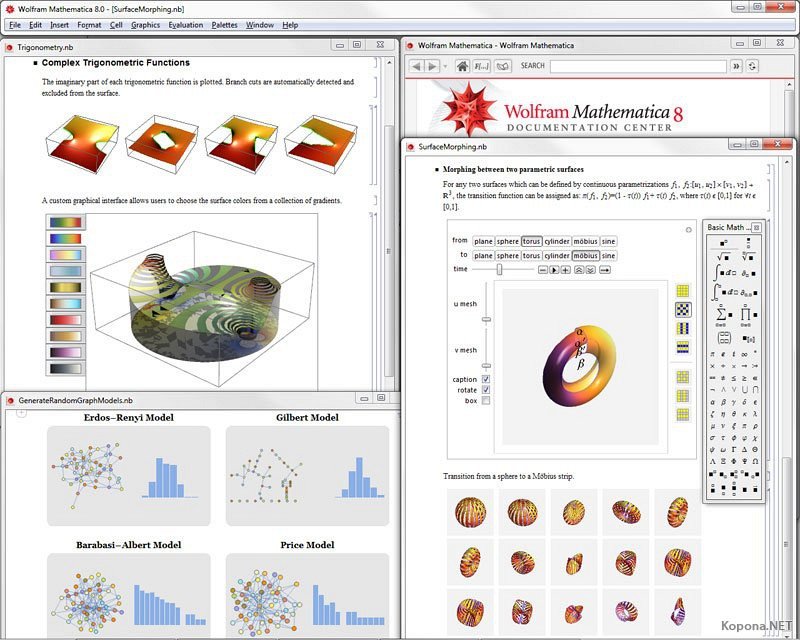

Maple

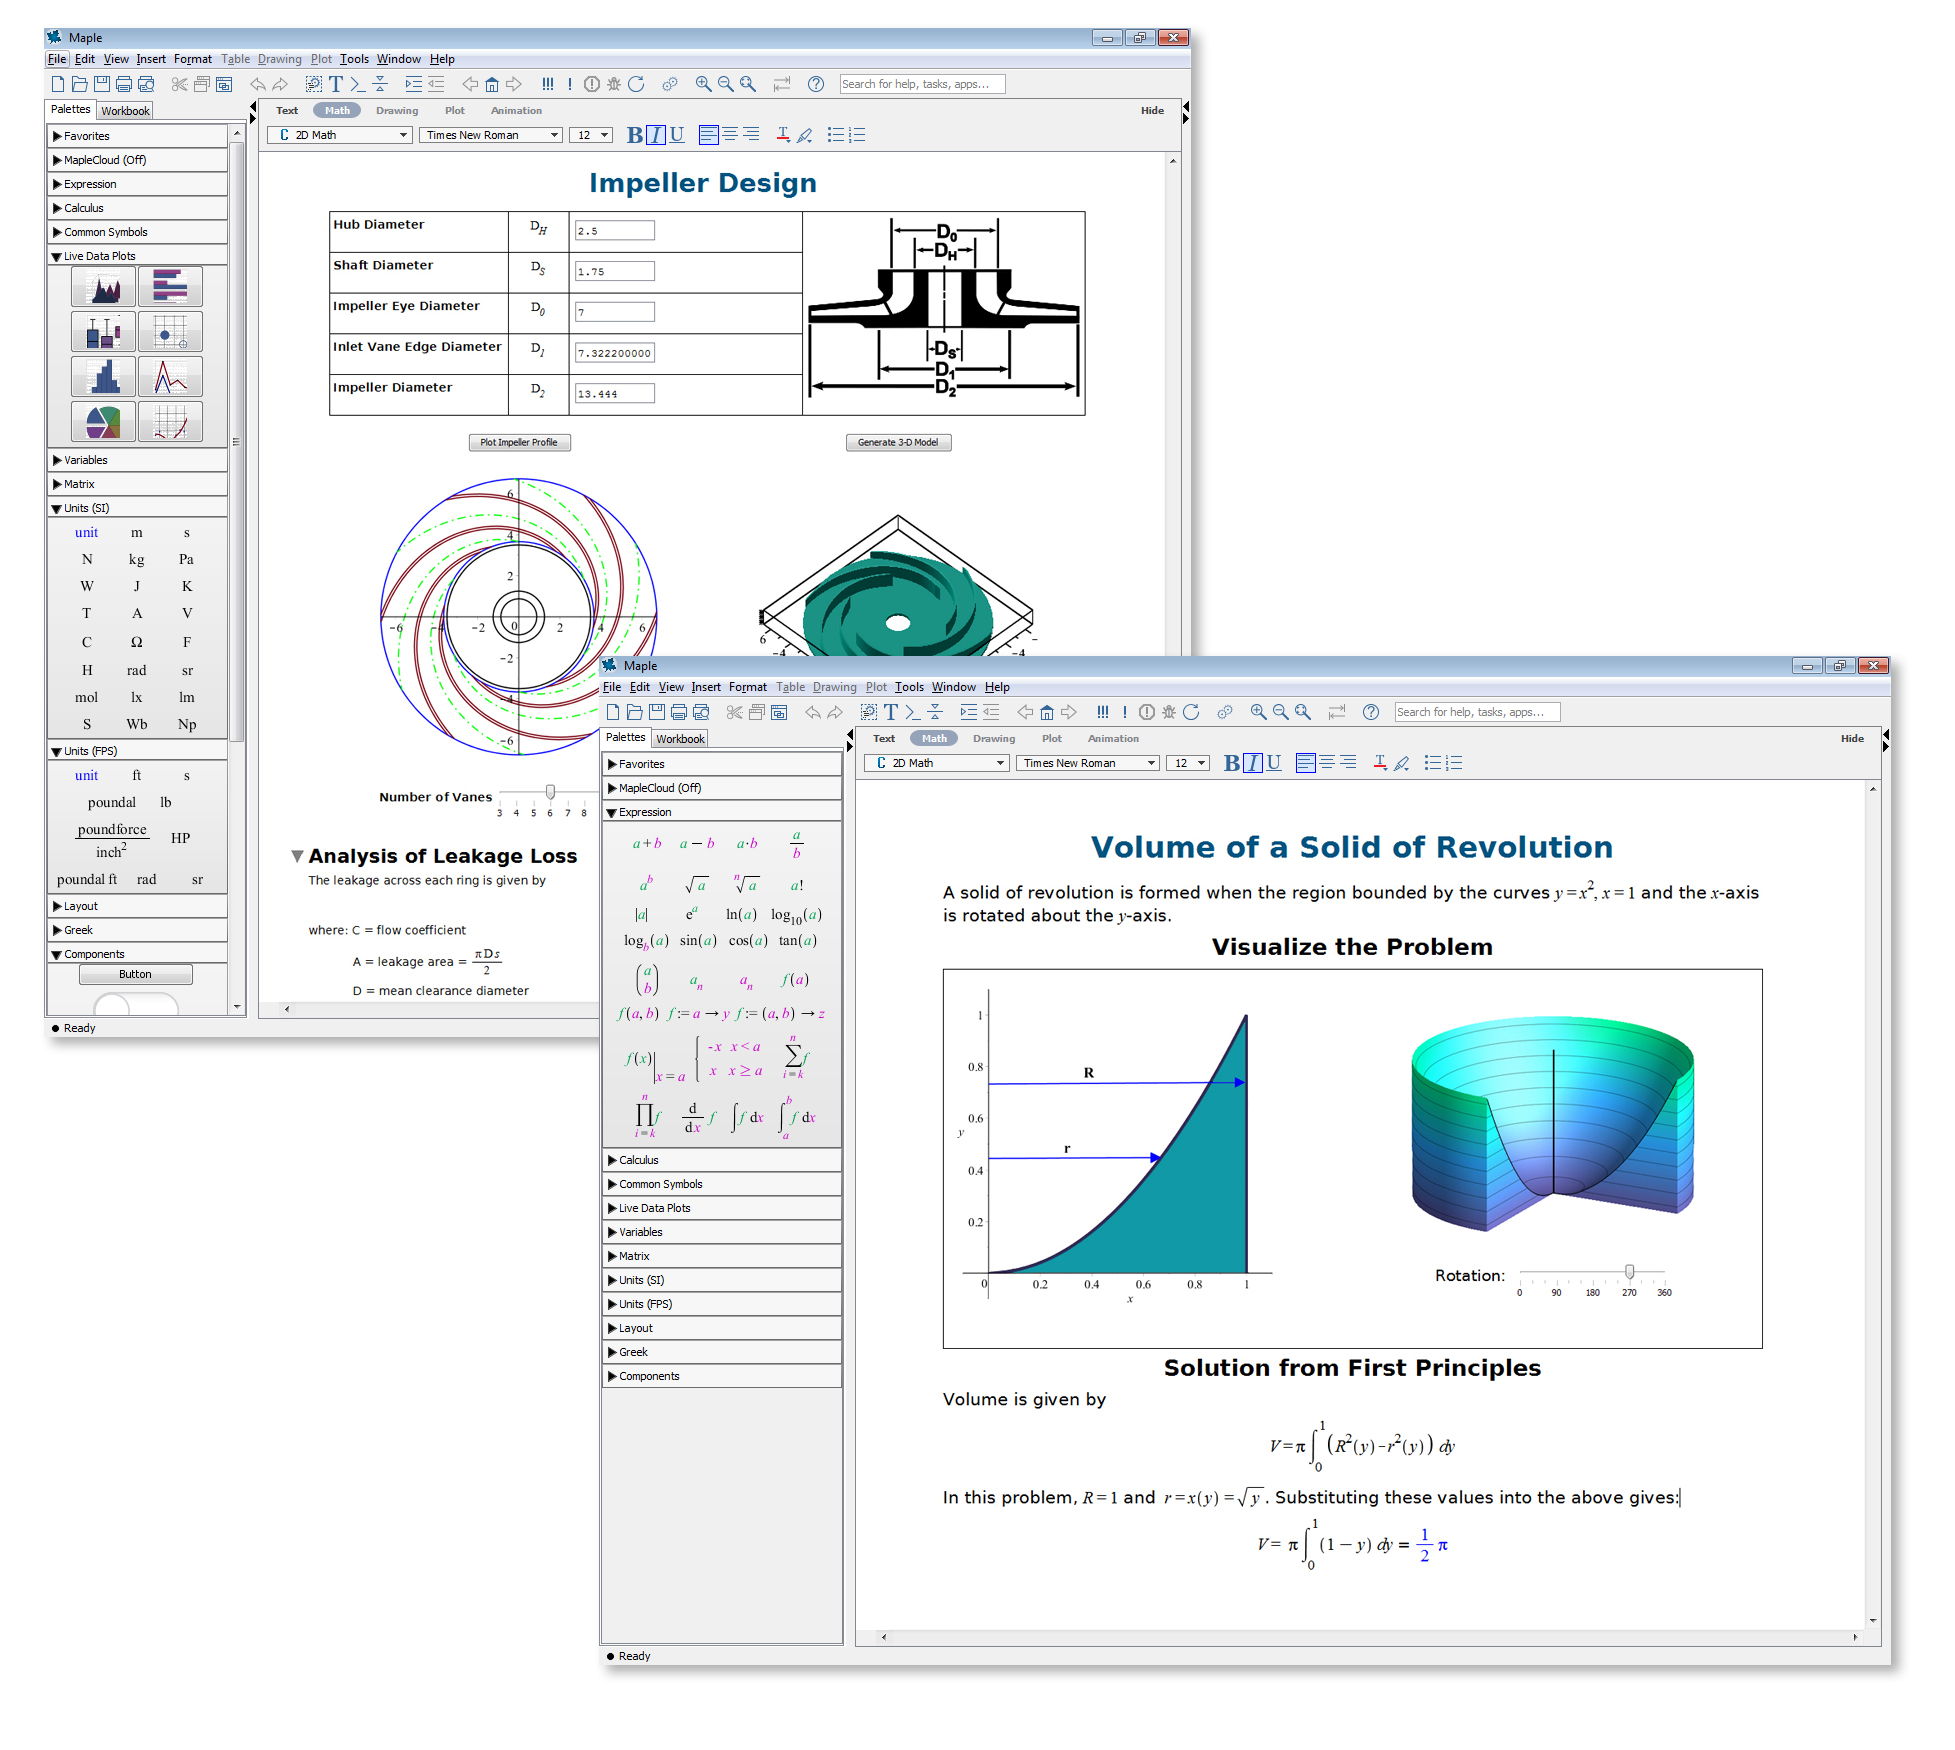

Mupad: 

**MuPAD**（**Mu**lti **P**rocessing **A**lgebra **D**ata Tool）是一个商用[计算机代数系统](https://zh.wikipedia.org/wiki/%E8%AE%A1%E7%AE%97%E6%9C%BA%E4%BB%A3%E6%95%B0%E7%B3%BB%E7%BB%9F)。最初由[德国](https://zh.wikipedia.org/wiki/%E5%BE%B7%E5%9B%BD)[帕德博恩大学](https://zh.wikipedia.org/wiki/%E5%B8%95%E5%BE%B7%E5%8D%9A%E6%81%A9%E5%A4%A7%E5%AD%A6)（Universität Paderborn）Benno Fuchsteiner教授的MuPAD研究小组开发而成，1997年以来，其开发由该研究小组与德国SciFace Software有限公司共同承担。2008年9月，SciFace公司被[The MathWorks](https://zh.wikipedia.org/wiki/The_MathWorks)公司收购，从此MuPAD作为符号数学工具箱（Symbolic Math Toolbox）被包含在[MATLAB](https://zh.wikipedia.org/wiki/MATLAB)当中。

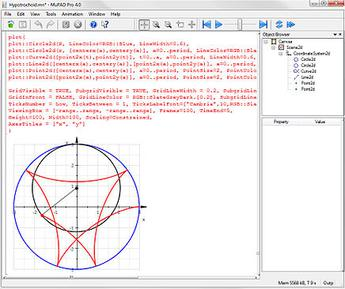

**1**`．符号对象`

`符号对象``是符号工具箱中定义的另一种数据类型。符号对象是用来存储代表符号的字符串，在符号工具箱中符号对象用于表示``符号变量、符号矩阵、符号表达式和符号方程``。`

`在数学计算中有数值计算与符号计算之分，数值计算的表达式、矩阵变量中不允许有未定义的自由变量，例如：`

A=[a,b;c,d]

函数或变量 'a' 无法识别。

`而符号计算可以含有未定义的符号变量，例如：`

syms a b c d
A = [a b c; c a b; b c a]

**2**`．符号对象与普通数据对象的差别`

`数学计算有数值计算与符号计算之分。这两者的根本区别是：`

- `数值计算的表达式、矩阵变量中不允许有未定义的自由变量。`

- `符号计算可以含有未定义的符号变量，在符号计算的整个过程中，所运算的是符号变量。需要注意的是，在符号计算中所出现的数字也都是当作符号处理的``。 `

`下例说明了符号对象和普通的数据对象之间的差别。 `

### **8.1.2  **`建立符号表达式和求值`

(1) `用`sym()`和`syms()`函数建立符号表达式。`

`用`sym()`函数建立符号表达式，其语法为`

**sym (**`符号变量`**)**

`例如，用`sym`命令创建：`

x=sym('x')
f=sin(x)

考虑另一个例子

y=sym('x')
f=sin(y)

`或用`syms()`命令创建，例如：`

syms x
f=sin(x)+cos(x)

$$f = \cos\left(x\right)+\sin\left(x\right)$$

考虑：符号 vs 符号变量

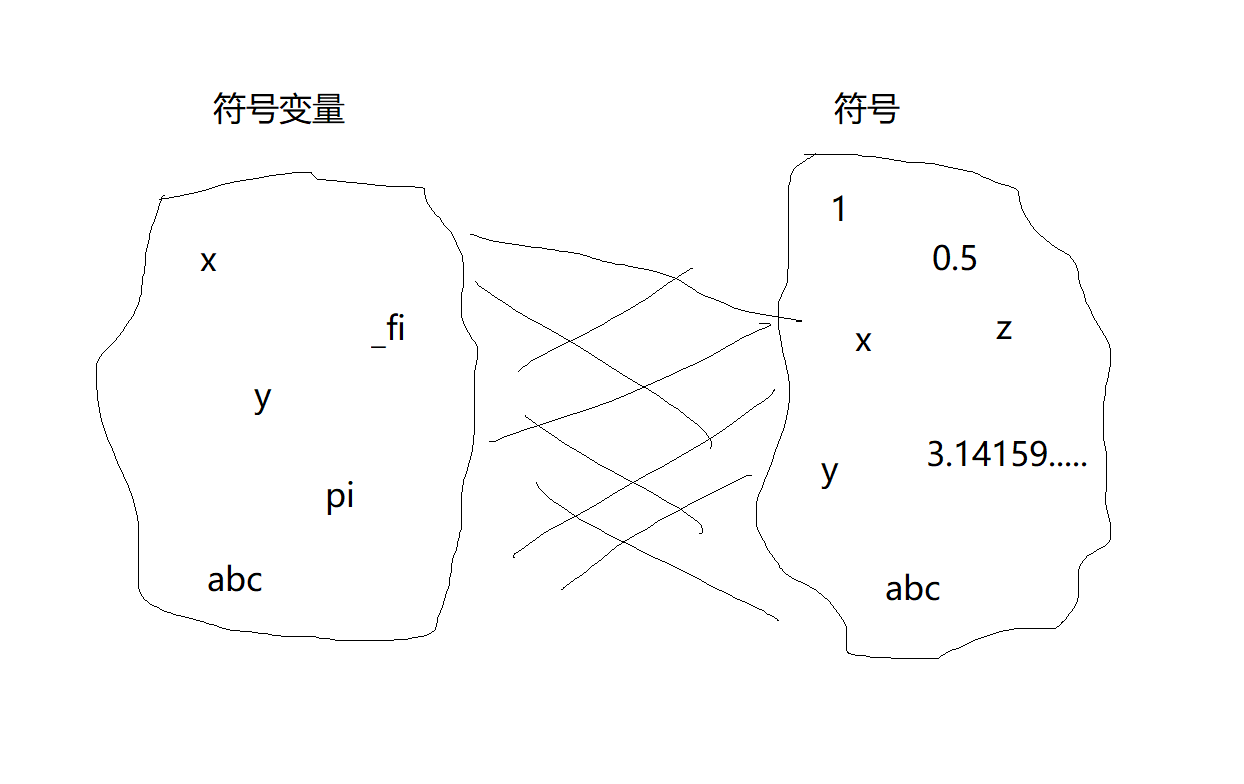

(2) `使用已经定义的符号变量组成符号表达式。例如：`

syms a b c x
f = a*x^2 + b*x + c

$$f = a\,x^{2}+b\,x+c$$

# **第8讲 符号运算**

**8.1  **`符号对象: sym, syms`

**8.2  **`数值与符号变量的相互转换: digits, vpa, double, poly2sym`

**8.3**  `符号矩阵与运算：+、-、*、/`

**8.4**  `符号表达式的化简: collect, expand, horner, symplify, factor，sub`**s，subexpr**

## 8.2  数值与符号变量的相互转换 

### **8.2.1  **`符号转换为数值`

`符号变量表示的值都是精确的，而数值变量表示的值可能是不精确的，有时符号运算的目的是得到精确的数值解，这就要对得到的解析解进行数值转换。 `

`我们在符号表达式转换为数值变量时要考虑到转换精度的问题。例如：`f=sym('1/3'); `将`f`定义为`1/3`，如果要转换为数值，那么我们应该转为`0.3`还是 `0.33333`呢`? `计算机存储总是有限制的，我们只能存储到有限个`3`。`

`使用`**digits()**`、`**vpa****()**`和`**double()**`函数进行符号与数值的转换。一般情况下，我们把这三个函数作为组合拳，先使用`digits()`设定精确程度，再使用`vpa()`作近似运算，最后才是`double()`转换为数值变量。`

**1**`．`**digits()**`函数`

digits(n)`：设置有效数字位数。该函数的作用是指定精确到多少`(n)`位有效数字，默认是`32`位。`

digits(100);
vpa(pi)

$$ans = 3.141592653589793238462643383279502884197169399375105820974944592307816406286208998628034825342117068$$

vpa(1/3)

$$ans = 0.3333333333333333333333333333333333333333333333333333333333333333333333333333333333333333333333333333$$

**2**`．`**vpa****()**`函数`

vpa(f)`将符号表达式`f`的结果精确到`digits()`所设定的有效数字的位数。值得注意的是，`**vpa****()**`返回的还是符号表达式``。命令形式如下：　　`

(1) R = vpa(A)`：根据当前指定的精度，使用可变精度算术`VPA`函数，计算`A`的每一个元素。结果中的每一个元素都是符号表达式。`

(2) R = vpa(A, d)`：使用`d`代替当前的精度，计算`A`的每一个元素，即求`A`在`d`精度下的数值解。`d`的值必须是正整数，而且位于`1`～`229+1`之间。`

vpa(pi, 10)

问题：

digits(12);
a = vpa(1/10)

$$a = 0.1$$

digits(12);
b = vpa(1/10)

$$b = 0.1$$

a - b

$$ans = 0.0$$

**3**`．`**double()**`函数`

double()`是将符号表达式转换为浮点数数值变量类型的函数。`double()`命令的形式如下：　　`

x = double(s)`：转换`s`为双精度型数值变量`x`，`s`可以是符号变量也可以是字符串变量。`

(1) `当`s`是符号变量时，`s`必须是全为数字的符号，返回数值变量`x`。例如：`

format short
s1=sym('20.3');
x1 = double(s1) % 把符号变量 s1 转化为数值变量 x1

## 例  举例说明符号对象和普通数据对象之间的差别。

解  在命令窗口中输入如下命令：

sqrt(2)

ans = 1.4142

x=sqrt(sym(2))

x = 2^(1/2)

由上例可以看出，当采用符号运算时，并不计算出表达式的结果，而是给出符号表达式。如果需要查看符号  x  所

表示的值，在窗口中输入：

double(x)

ans = 1.4142

重新考虑0.5-0.48 == 0.02的问题：

x = sym(0.5);
y = sym(0.48);
z = x - y
double(z) == 0.02

### **8.2.3  poly2sym()函数与多项式的符号表达式**

`poly2sym()函数可以把多项式用符号表达式表示出来。用法如下：`

r = poly2sym(c)`：返回多项式的符号表达式，多项式的系数是数字向量`c`。默认符号表达式的变量是`x`，变量`v`可以指定作为第二个参数。 `

## 
$$r=c_1 x^{n-1} +c_2 x^{x-2} +\ldotp \ldotp \ldotp +c_n$$


`例如：`

y=[ 1  -12  44  -48  0]

y =      1   -12    44   -48     0


ya=poly2sym(y) 

$$ya = x^{4}-12\,x^{3}+44\,x^{2}-48\,x$$

# **第8讲 符号运算**

**8.1  **`符号对象: sym, syms`

**8.2**  `数值与符号变量的相互转换: digits, vpa, double, poly2sym`

**8.3  **`符号矩阵与运算：+、-、*、/`

**8.4**  `符号表达式的化简: collect, expand, horner, symplify, factor，sub`**s，subexpr**

## 8.3 符号矩阵与运算

### **8.3.1 符号矩阵的索引和修改**

**sym()**`的另一个重要作用是将数值矩阵转化为符号矩阵。` 

例 符号矩阵的索引。

 解 程序如下：

 a=[2/3,sqrt(2),0.222;1.4,1/0.23,log(3)]

a =     0.6667    1.4142    0.2220
    1.4000    4.3478    1.0986


 b=sym(a)

$$b = \left(\begin{array}{ccc} \frac{2}{3} & \sqrt{2} & \frac{111}{500}\\ \frac{7}{5} & \frac{100}{23} & \frac{2473854946935173}{2251799813685248} \end{array}\right)$$

1．符号矩阵的索引

直接对符号矩阵的元素索引。

 b(1,3) %矩阵的索引

�2．符号矩阵的修改

(1) 直接修改。可用矩阵元素下标，直接修改。

 b(2,3)='3/5' %矩阵的修改

### �**8.3.2 符号矩阵的四则运算**

1．基本运算

符号矩阵的基本运算符与数值矩阵的运算符是统一的(+ - * / \)。符号矩阵的数值运算中，与数值矩阵一样，是对应元素的运算。所有矩阵运算操作指令都比较直观、简单，如

**a=b+c; a=a*b；A=2*a^2+3*a-5**。

符号矩阵的行列式运算、逆运算、求秩、幂运算、数组指数运算、矩阵指数运算使用：det(a)、inv(b)、rank(a)、a^2、exp(b)、expm(b)。

��解 (1)

x = sym('x')

$$x = x$$

a = [1/x,1/(x+1); 1/(x+2), 1/(x+3)]

$$a = \left(\begin{array}{cc} \frac{1}{x} & \frac{1}{x+1}\\ \frac{1}{x+2} & \frac{1}{x+3} \end{array}\right)$$

b = [x,1;x+2,0]

$$b = \left(\begin{array}{cc} x & 1\\ x+2 & 0 \end{array}\right)$$

b-a

$$ans = \left(\begin{array}{cc} x-\frac{1}{x} & 1-\frac{1}{x+1}\\ x-\frac{1}{x+2}+2 & -\frac{1}{x+3} \end{array}\right)$$

a\b

$$ans = \left(\begin{array}{cc} -x\,\left(2\,x^{2}+7\,x+6\right) & \frac{x\,\left(x^{2}+3\,x+2\right)}{2}\\ 2\,{\left(x+1\right)}^{2}\,\left(x+3\right) & -\frac{x\,\left(x+1\right)\,\left(x+3\right)}{2} \end{array}\right)$$

% a/b = a*(1/b)
% a\b = (a)^(-1)*b

**补充材料：**

Solve a simple system of linear equations, `A*x = B`.

x = A^(-1)*b= A\b

代码：

A = magic(3);
B = [15; 15; 15];
x = A\B

x =     1.0000
    1.0000
    1.0000


�(2)  

syms x
f=2*x^2+3*x-5

$$f = 2\,x^{2}+3\,x-5$$

g= x^2+x-7

$$g = x^{2}+x-7$$

h=f+g

$$h = 3\,x^{2}+4\,x-12$$

h = 3*x^2+4*x-12

$$h = 3\,x^{2}+4\,x-12$$

(3)  

syms x
f=cos(x);g=sin(2*x);
f/g+f*g

# **第8讲 符号运算**

**8.1  **`符号对象: sym, syms`

**8.2**  `数值与符号变量的相互转换: digits, vpa, double, poly2sym`

**8.3  **`符号矩阵与运算：+、-、*、/`

**8.4  **`符号表达式的化简: collect, expand, horner, symplify, factor，sub`**s，subexpr**

## **8.4 符号表达式的化简**

### **8.4.1 合并多项式**

collect()函数用于合并多项式中的同类项，具体调用格式如下：

(1) R = collect(S)，该命令将S中的每个元素，按默认变量x的阶数

进行同类项系数合并，其中S可以是数组，数组的每个元素为符号表达式。

## 例 合并多项式。

解 程序如下：

syms x t;
f=(1+x)*t+x*t
collect(f)

ans = 2*t*x + t

(2) R = collect(S,v)，对指定的变量v进行合并，如果不指定，则默认为对x进行合并，或者由findvar()函数返回的结果进行合并。

�8.4.2 展开多项式

expand()函数用于符号表达式的展开。调用格式如下：

expand(S)：对符号表达式S中每个因式的乘积进行展开

计算。该命令通常用于计算多项式函数、三角函数、指数函数和对数函数等表达式的展开。

##  例 符号表达式的展开。

 解 程序如下：

 syms x
 f=x*(x*(x-1)+3)+2

$$f = x\,\left(x\,\left(x-1\right)+3\right)+2$$

 y=expand(f)

$$y = x^{3}-x^{2}+3\,x+2$$

 y = x^3 - x^2 + 3*x + 2

$$y = x^{3}-x^{2}+3\,x+2$$

 syms x
 f = (x+1)*(x+3)

$$f = \left(x+1\right)\,\left(x+3\right)$$

 y = expand(f)

$$y = x^{2}+4\,x+3$$

### **�8.4.3 转换多项式**

与expand()函数相反，horner()函数把多项式转换为Horner形式，这种形式的特点是乘法嵌套，有着较好的数值计算性质，嵌套格式在多项式求值中可以降低计算时的复杂度。该函数的调用格式如下：

### R = horner(P)

其中，P为由符号表达式组成的矩阵，该命令将 P 中的所有元素转化为相应的嵌套形式。

注：秦九韶算法是中国南宋[时期](https://baike.baidu.com/item/%E6%97%B6%E6%9C%9F/7856877)的数学家[秦九韶](https://baike.baidu.com/item/%E7%A7%A6%E4%B9%9D%E9%9F%B6/363167)提出的一种[多项式](https://baike.baidu.com/item/%E5%A4%9A%E9%A1%B9%E5%BC%8F/10660961)[简化](https://baike.baidu.com/item/%E7%AE%80%E5%8C%96/3374416)算法。在西方被称作霍纳算法。[秦九韶](https://baike.baidu.com/item/%E7%A7%A6%E4%B9%9D%E9%9F%B6/363167)（约公元1202年－1261年），字道古，南宋末年人，出生于鲁郡（今山东曲阜一带人）。

## �**例 转换多项式。**

解 程序如下：

syms x;
y = x^3 - x^2 + 3*x + 2
horner(y)

   ans = x*(x*(x-1)+3)+2

### **�8.4.4 简化多项式**

1．化简函数simplify()

simplify()函数通过数学运算实现符号表达式的化简。例如：

syms x ;
f=sin(x)^2+cos(x)^2
simplify(f)

ans =1

### �**8.4.5 因式分解与factor()函数**

factor()函数实现因式分解功能，如果输入的参数为正整数，则返回此数的素数因数。如果无法在有理数的范围内作分解，那么返回的结果还是输入值。语法格式如下：

factor(X)：参量X可以是正整数、符号表达式矩阵或符号整数矩阵。若X为一正整数，则factor(X)返回X的质数分解式。若X为多项式或整数矩阵，则factor(X)分解矩阵的每一元素。若整数矩阵中有一元素位数超过16位，用户必须用sym命令生成该元素。

## �**例 将**$f=x^3 -6x^2 +11x-6$**进行因式分解。**

解 程序如下：

syms x;
f=x^3-6*x^2+11*x-6;
factor(f)

ans =[ x - 3, x - 1, x - 2]

### ��**8.4.6 符号替换**

 1．subs() 函数

 subs()函数可以在一符号表达式或矩阵中进行符号替换，用指定符号替换表达式中的某一特定符号，如将符号表达式中的符号变量用数值代替。

在对多变量符号表达式使用subs()函数时，如果不指定变量，则系统选择默认变量进行计算。默认变量的选择规则为：选择在字母表中离x 近的变量字母作为默认变量，如果有两个变量并且和 x 之间的距离相同，则选择字母表靠后面的变量作为默认变量。

�subs()函数的调用格式如下：

(1) R = subs(S)。对于S中出现的全部符号变量，如果在调用函数或工作空间中存在相应值，则将值代入，同时自动进行化简计算；若是数值表达式，则计算出结果。如果没有相应值，则对应的变量保持不变。

(2) R = subs(S, new)。用新的符号变量new替换S中的默认变量，即有findsym()函数返回的变量。

(3) R = subs(S, old, new)。用新值new替换表达式S中的旧值old，参量old是一符号变量或代表一变量名的字符串，new是一符号、数值变量或表达式。

�若old与new是具有相同大小的阵列，则用new中相应的元素替换old中的元素；若S与old为标量，而new为阵列或单元阵列，则标量S与old将扩展为与new同型的阵列；将S中的所有old替换为new，并将S中的常数项扩充为与new维数相同的常数矩阵。

若new为数值矩阵的单元阵列，则替换按元素的方向执行。

若new是数字形式的符号，则数值代替原来的符号计算表达式的值，所得结果仍是字符串形式。

## �例 使用subs()指令修改符号矩阵：

解 程序如下：

syms a b
A =[ a, 2*b;3*a, 0]

$$A = \left(\begin{array}{cc} a & 2\,b\\ 3\,a & 0 \end{array}\right)$$

A(2,2) = 4*b

$$A = \left(\begin{array}{cc} a & 2\,b\\ 3\,a & 4\,b \end{array}\right)$$

A1 = [ a, 2*b; 3*a, 4*b]

$$A1 = \left(\begin{array}{cc} a & 2\,b\\ 3\,a & 4\,b \end{array}\right)$$

A2 = subs(A2, 4*b, 2*c)

函数或变量 'A2' 无法识别。

A2 = subs(A2, 2*b, c)
A3 = [ a, 2*b; 3*a, 2*(2*b)]
A4 = subs(A3, 2*b, c)

## **例如，**使用subs()指令修改函数**：**

syms C a t
y = C / exp(a*t)
a = 980,C=3;
subs(y)

 ans =

 3/exp(980*t)

用a、C1值替换表达式中的变量值。

�   2．subexpr() 函数

   subexpr()函数通过计算机自动寻找，将表达式中多次重复出现的因式或字符串用简短的符号或变量替换，返回的结果中包含替换之后的表达式，以及被替换的因式。该函数的调用格式如下：

  (1) [Y,SIGMA] = subexpr(X,SIGMA)。指定用符号变量SIGMA来代替符号表达式X中(可以是矩阵)重复出现的字符串。替换后的结果由Y返回，被替换的字符串由SIGMA返回。例如：

syms x a;
                        
f=solve(x^2+a*x-1)    
r=subexpr(f);  
r     

结果：sigma =(a^2 + 4)^(1/2)

r= - a/2 - sigma/2

    sigma/2 - a/2

�